% IIR filters
clear all;
clc;

% Realising IIR filters
fs = 500;

% Low-pass filter
n_l = 45; % Low pass filter order
Wn_l = 140/(fs/2);

[b_low, a_low] = butter(n_l, Wn_l, "low");

% Visualization
%fvtool(b_low, a_low);

% High-pass filter
n_h = 6;
Wn_h = 1/(fs/2);

[b_high, a_high] = butter(n_h, Wn_h, 'high');
%fvtool(b_high, a_high);

% Frequency to be notched out (fo)
fo = 50;  % in Hz

% Quality factor (q) determines how sharp or narrow the notch is
q = 50;  % Higher value = sharper notch, lower value = wider notch

% Calculate the bandwidth of the notch filter
bw = (fo/(fs/2))/q;  % Bandwidth relative to the Nyquist frequency (fs/2)

% Design the comb filter
% The function iircomb creates a comb filter, with fs/fo determining the spacing of notches
% 'notch' specifies that we want the filter to remove (notch) those frequencies
[b_comb, a_comb] = iircomb(fs/fo, bw, 'notch');

% Visualize the frequency response of the filter using Filter Visualization Tool (FVTool)
%fvtool(b_comb, a_comb);

% Combine all three filters
Low_pass = dfilt.df1(b_low, a_low);
High_pass = dfilt.df1(b_high, a_high);
Comb = dfilt.df1(b_comb, a_comb);
Cascaded_filter = dfilt.cascade(Low_pass,High_pass,Comb);

% Plot the frequency response 
%freqz(Cascaded_filter, 1024)

% Filtering methods using IIR filters
load("ECG_with_noise.mat")
time = (0:length(nECG)-1)/fs;

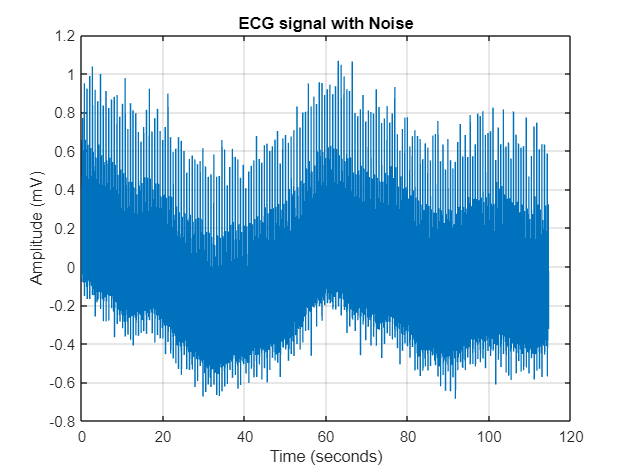

% Apply forward filtering
ECG_forward_IIR = filter(Cascaded_filter, nECG);


figure;
plot(time, nECG);
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('ECG signal with Noise');
grid on; 

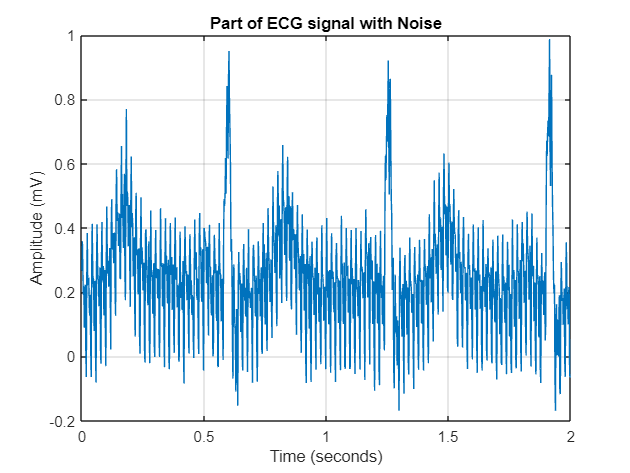


figure;
plot(time(1:1000), nECG(1:1000));
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Part of ECG signal with Noise');
grid on; 

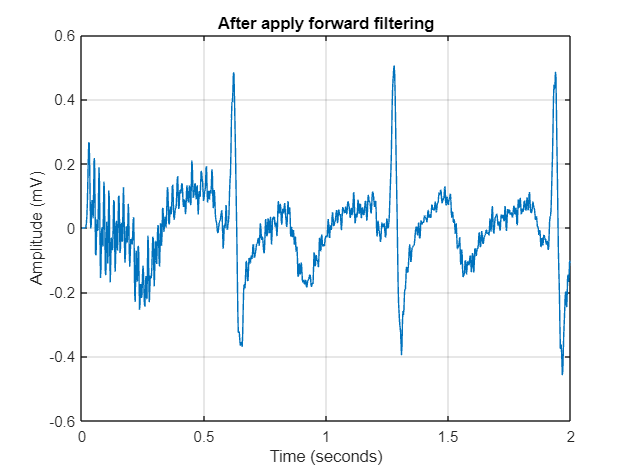


figure;
plot(time(1:1000), ECG_forward_IIR(1:1000));
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('After apply forward filtering');
grid on;  

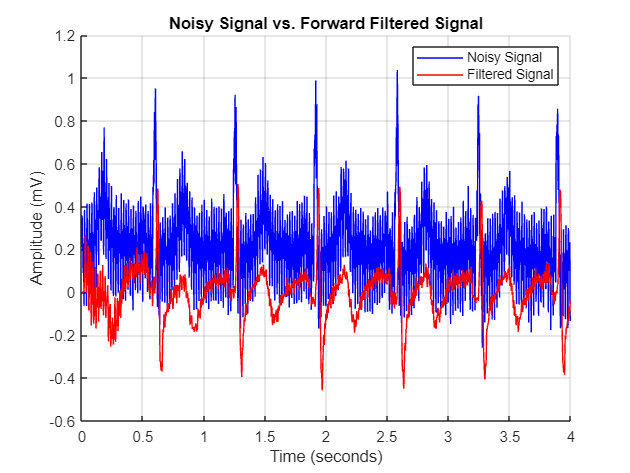


figure;
hold on;  % Keep the current plot
plot(time(1:2000), nECG(1:2000), 'b-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red dashed line
plot(time(1:2000), ECG_forward_IIR(1:2000), 'r-', 'DisplayName', 'Filtered Signal');  % Filtered signal in solid blue line
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Forward Filtered Signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

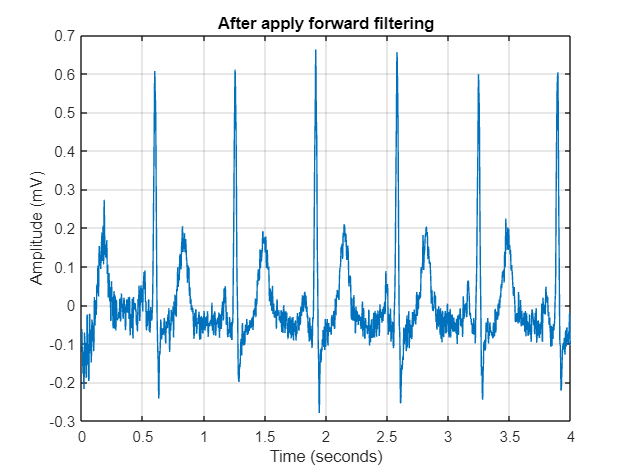

% Apply forward-backward filtering using IIR filters
filtered_ecg_1 = filtfilt(b_low, a_low, nECG);
filtered_ecg_2 = filtfilt(b_high, a_high, filtered_ecg_1);
IIR_forward_backward_filtered_ecg = filtfilt(b_comb, a_comb,filtered_ecg_2 );

figure;
plot(time(1:2000), IIR_forward_backward_filtered_ecg(1:2000));
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('After apply forward filtering');
grid on;  

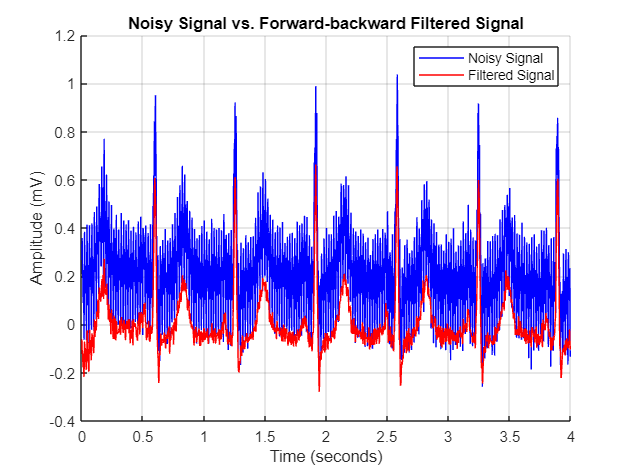


figure;
hold on;  % Keep the current plot
plot(time(1:2000), nECG(1:2000), 'b-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red dashed line
plot(time(1:2000), IIR_forward_backward_filtered_ecg(1:2000), 'r-', 'DisplayName', 'Filtered Signal');  % Filtered signal in solid blue line
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Forward-backward Filtered Signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

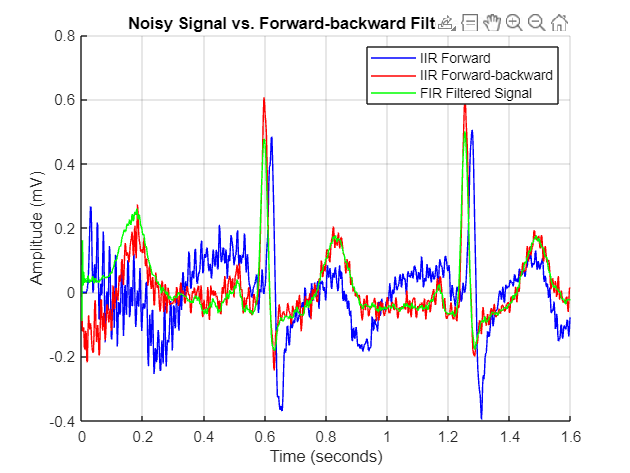

load("FIR_filtered_ECG.mat")

figure;
time_ = 1:800;
hold on;  % Keep the current plot
plot(time(time_), ECG_forward_IIR(time_), 'b-', 'DisplayName', 'IIR Forward');  % Noisy signal in red dashed line
plot(time(time_), IIR_forward_backward_filtered_ecg(time_), 'r-', 'DisplayName', 'IIR Forward-backward');  % Filtered signal in solid blue line
plot(time(time_), FIR_filtered_ECG(time_), 'g-', 'DisplayName', 'FIR Filtered Signal');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Forward-backward Filtered Signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

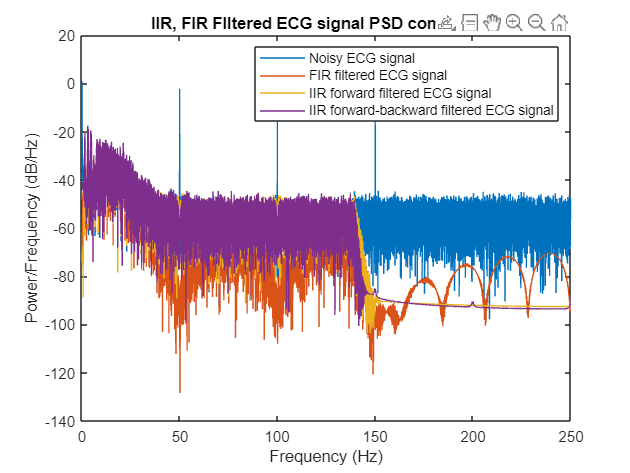

window = rectwin(length(FIR_filtered_ECG)); % to avoid spectral leakage
nfft = length(FIR_filtered_ECG);
[PSD_nECG, f_f] = periodogram(nECG, window , nfft, fs);
[PSD_FIR, ~] = periodogram(FIR_filtered_ECG, window , nfft, fs);
[PSD_IIR_f, ~] = periodogram(ECG_forward_IIR, window , nfft, fs);
[PSD_IIR_f_b, ~] = periodogram(IIR_forward_backward_filtered_ecg, window , nfft, fs);

figure(4)
plot(f_f, 10*log10(PSD_nECG), f_f, 10*log10(PSD_FIR), f_f, 10*log10(PSD_IIR_f), f_f, 10*log10(PSD_IIR_f_b));
legend('Noisy ECG signal', 'FIR filtered ECG signal',...
    'IIR forward filtered ECG signal', 'IIR forward-backward filtered ECG signal');
title('IIR, FIR FIltered ECG signal PSD comparison');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');